# 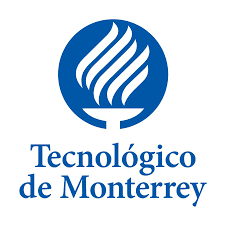

# Estimación de volumen perdido en un evento de fuga en un contenedor de combustibles

Autor: **Dr. Rodolfo Salazar Peña**

Instituto Tecnológico de Monterrey, Campus Guadalajara, México

rodolfo.salazar@tec.mx

clear
close all
clc
warning off

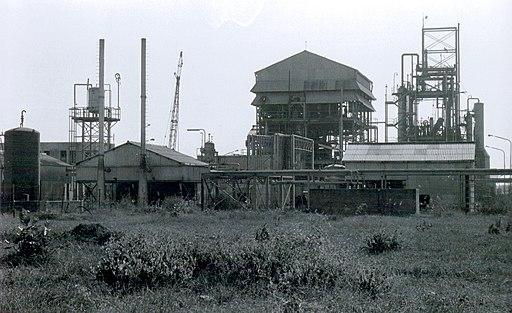

**Figura 1.** Vista exterior de la fábrica de pesticidas Union Carbide en Bhopal, India, escenario de uno de los peores desastres industrial durante 1984-1985. La fábrica permanece en ruinas y abandonada y allí se almacenan en la superficie aproximadamente 350 toneladas métricas de residuos tóxicos. By Bhopal Medical Appeal, Martin Stott, CC BY-SA 2.0.

## Resumen

*Los eventos de fuga en plantas químicas son un potencial peligro que debe ser considerados incluso desde el diseño mismo (Fig. 1). Es particularmente útil simular este tipo de situaciones de contingencia y de esta manera poder planificar la implementación de contramedidas de control y mitigación en estos escenarios. En esta contribución se presenta un proyecto académico en el que se modela y simula una hipotética fuga de un líquido combustible en un contenedor cilíndrico. Se utiliza MATLAB para desarrollar de la simulación así como Simscape con su módulo de líquidos isotérmicos como alternativa para que los estudiantes tengan opciones y comparen resultados obtenidos.*

*Palabras Clave: Seguridad Industrial, Análisis de Riesgos Industriales, Diseño Integral de Procesos Químicos, Ingeniería Química, Modelado matemático*

## Objetivos de Aprendizaje

### Objetivo General

Aplicar un modelo de vaciado hidráulico de un tanque de almacenamiento. En principio, éste recipiente puede contener una sustancia líquida tóxica, corrosiva, inflamable o de cualquier otro tipo de peligrosidad. El modelo es particularmente útil para diseñar y desarrollar medidas de contingencia ante un eventual evento de fuga.

### Objetivos Particulares

- Desarrollar un modelo hidráulico del vaciado de un tanque de almacenamiento cilíndrico con eje el axial vertical.

- Generar una herramienta interactiva  con para determinar volumen y masa del líquido derramado durante un evento de fuga en un periodo determinado de tiempo.

- Realizar una comparativa entre diversas estrategias de cómputo y simulación, estas pueden ser, solución analítica de las ecuaciones diferenciales del modelo hidráulico, solución numérica utilizando los [*solvers *de MATLAB](https://la.mathworks.com/help/matlab/ordinary-differential-equations.html) y/o [Simulink](https://la.mathworks.com/help/simulink/index.html) con su módulo de [Simscape](https://la.mathworks.com/help/simscape/index.html).

## Problema a resolver

Dentro de una planta química existe un tanque cilíndrico de almacenamiento de gasolina (ver Fig. 2). 

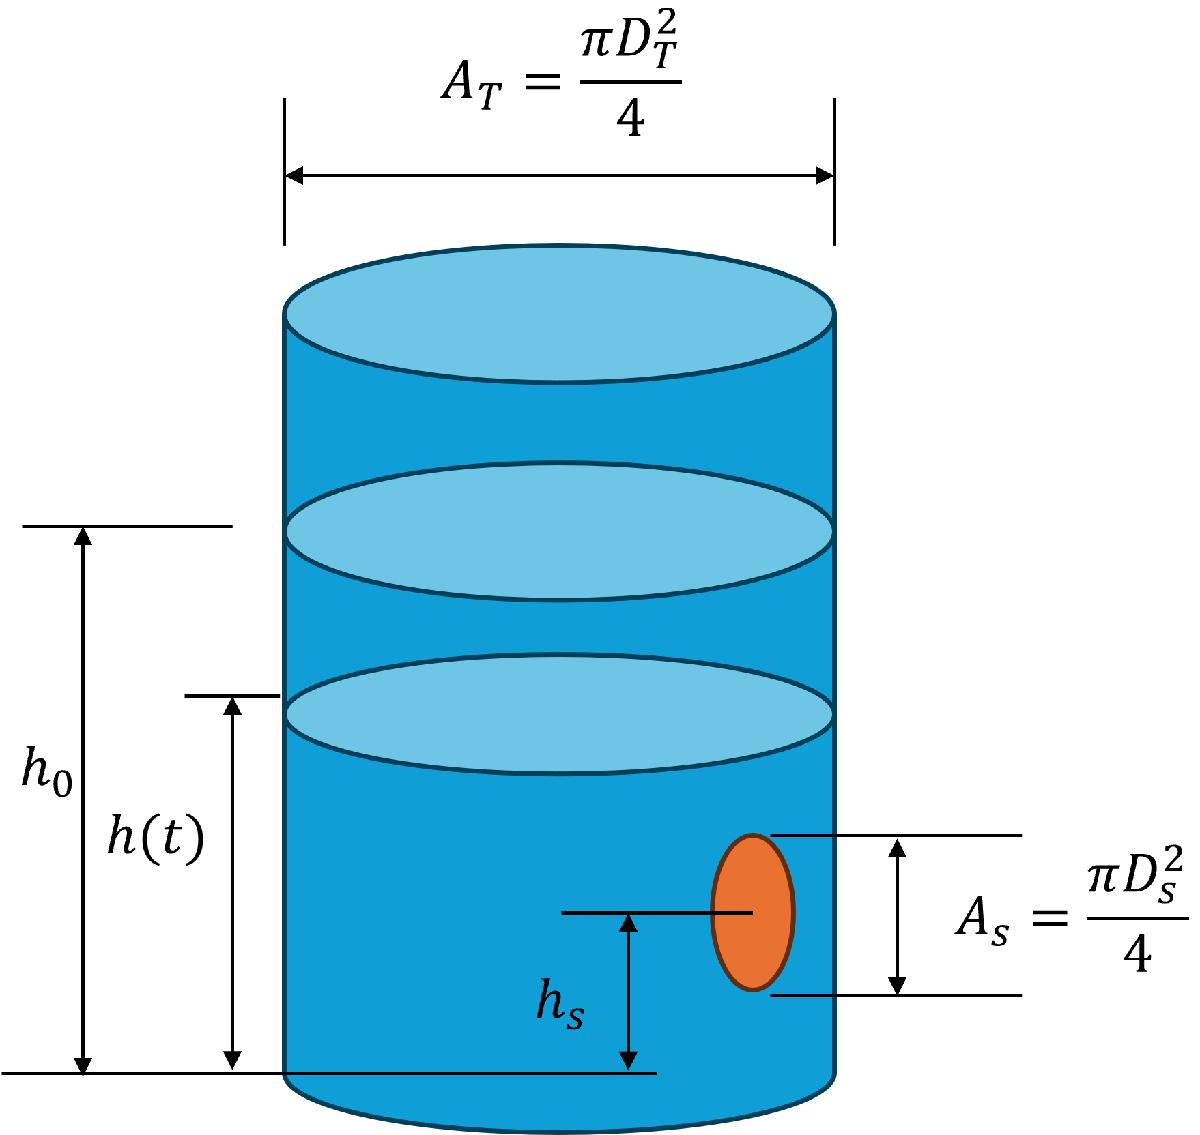

**Figura 2.** Esquemático del tanque de almacenamiento y dimensiones.

Las dimensiones del tanque son diámetro transversal del tanque $D_T=25\,\mathrm{m}$, altura $H=4\,\mathrm{m}$, y opera normalmente a un 80% de su capacidad total. El tanque cuenta con un tubo de descarga de diámetro $D_s=3\,\mathrm{in}$, en el cual se encuentra instalada una válvula de globo. El tubo se utiliza para trasvasar gasolina del tanque a pipas que lo transportarán a los lugares de uso dentro de la planta. La tubería se encuentra al nivel del piso por un costado del tanque. Los sistemas convencionales de contención de fugas pueden llegar a tardar hasta $t_f=18\,\mathrm{h}$ en contener la fuga. Estime la cantidad de gasolina derramada si se llega a romper la tubería de descarga durante ese intervalo de tiempo. Considere las siguientes simplificaciones: 

- Desprecie los efectos de [fricción hidráulica](https://es.wikipedia.org/wiki/Factor_de_fricci%C3%B3n_de_Fanning).

- Considere que la superficie del líquido en la parte superior del contenedor está abierto pequeña abertura a la atmósfera, esto con una pequeña abertura que hace que el contenedor nunca se encuentre presurizado.

- Considere que la altura de la salida es $h_s=0$, ya que como se indica en el enunciado del problema, está se encuentra a nivel del piso.

## Creación del modelo hidráulico

El modelo de descarga se inicia con un [balance de materia](https://es.wikipedia.org/wiki/Balance_de_materia) sin generación ni consumo de masa: Acumulación = Entrada - Salida. Puesto que en este caso en particular la entrada es igual a cero, ya que solo existe salida, y esto hace que inherentemente se tenga un estado no estacionario. Se tiene entonces que,


$$\frac{\mathrm{d}m}{\mathrm{d}t}=-\rho Q_s\quad m(0)=m_0$$


siendo $m$ y $m_0$ las masas de gasolina en el contenedor en todo momento y la masa inicial del combustible respectivamente, ambas en kg, $\rho$ la densidad de la gasolina en $\mathrm{kg\,m^{-3}}$, y $$Q_s$$ el [caudal](https://es.wikipedia.org/wiki/Caudal_(fluido)) (flujo volumétrico) de salida en $\mathrm{m^3\,s^{-1}}$. La masa de gasolina dentro del contenedor se puede calcular por $m=\rho V=\rho A_Th$, siendo $V$ el volumen de gasolina dentro del contenedor en $\mathrm{m}^3$, $A_T$ es el área transversal del tanque en $\mathrm{m}^2$ y $h$ la altura (nivel) del fluido dentro del tanque en $\mathrm{m}$.  

El tanque es cilíndrico, entonces su área transversal es constante. La gasolina se encuentra en estado líquido, por lo que se considera [fluido incompresible](https://es.wikipedia.org/wiki/Flujo_incompresible) y su densidad es constante. Por todo lo anterior se tiene que


$$\rho A_T\frac{\mathrm{d}h}{\mathrm{d}t}=-\rho A_sv\quad h(0)=h_0$$


siendo $A_s$ el área transversal de la tubería salida en $\mathrm{m}^2$, $v$ la velocidad lineal (promedio) del flujo de salida del líquido en $\mathrm{m\,s^{-1}}$, y $h_0$ la altura (nivel) inicial de la columna de líquido.

Puesto que para un círculo, $A=\pi D^2/4$, y la velocidad de salida del fluido, dada la columna del líquido, se puede determinar por el [Teorema de Torricelli](https://es.wikipedia.org/wiki/Teorema_de_Torricelli) (ver [principio hidrodinámico de Bernoulli](https://es.wikipedia.org/wiki/Principio_de_Bernoulli)), se tiene entonces que


$$D_T^2\frac{\mathrm{d}h}{\mathrm{d}t}=-D_s^2\sqrt{2gh}\quad h(0)=h_0$$


siendo $g=9.81\,\mathrm{m\,s^{-2}}$, la [constante de aceleración gravitacional](https://es.wikipedia.org/wiki/Gravedad_est%C3%A1ndar).

g=127137600;     % m h^-2 aceleración gravedad

Simplificando se tiene


$$\frac{\mathrm{d}h}{\mathrm{d}t}=-c\sqrt{h}\quad h(0)=h_0$$


siendo


$$c=\left(\frac{D_s}{D_T}\right)^2\sqrt{2g}$$


en $\mathrm{m^{1/2}\,s^{-1}$.

Resolviendo la ecuación diferencial se tiene que


$$h=\left(\sqrt{h_0}-\frac{ct}{2}\right)^2$$


y el volumen perdido


$$V_P=\frac{\pi D_T^2}{4}(h_0-h)$$


## Simulación

 Ejecute el *LiveScript* de manera general la primera ocasión.

Diámetro transversal del tanque $D_T,\,\mathrm{m}$.             Áltura total del tanque $H,\,\mathrm{m}$.          Porcentaje utilizado del tanque        Diámetro descarga $D_s,\,\mathrm{in}$.      Duración del evento de fuga $t_f\,\,\mathrm{h}$.

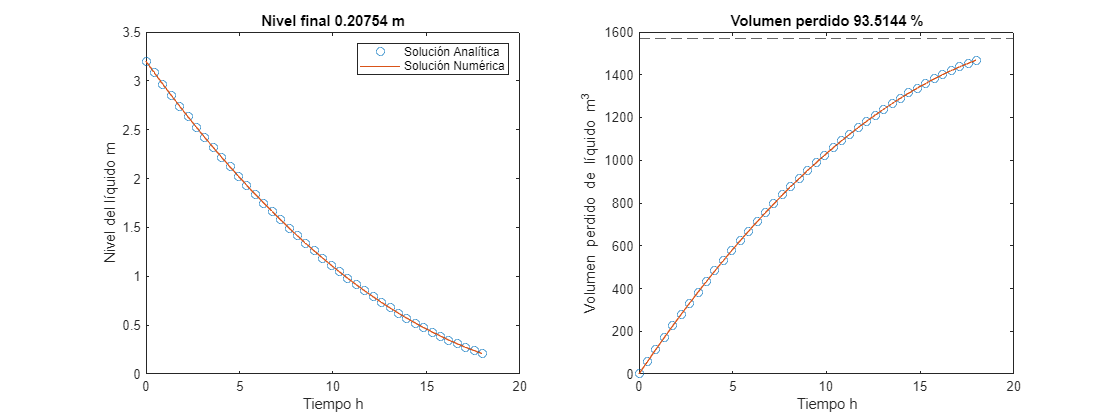

DT=25;H=4;C=80;Ds=3; tf=18;
n=40;

% Cálculos Solución Analítica
C=C/100;                % Fracción volumen tanque
h0=C*H;                 % m Altura inicial
Dsm=0.0254*Ds;          % m Diámetro descarga m 
t=linspace(0,tf,n+1);   % Divisiones    
c=sqrt(2*g)*(Dsm/DT)^2; % Constante c
h=(sqrt(h0)-c*t/2).^2;  % m Nivel del líquido
V=@(y)pi*DT^2*y/4;
V0=V(h0);               % m^3 Volumen inicial
Vp=V0-V(h);             % m^3 Volumen perdido

% Cálculos MATLAB ODE Solvers
f=@(tempo,x)-c*sqrt(x);
[tbis,hbis]=ode45(f,t,h0);
Vpbis=V0-V(hbis);

% Datos para alimentar la simulación con modelo en Simscape
th=t'*3600;
siminh=[th h'];
siminV=[th Vp'];

% Determinación de vaciado total en base a la función analítica
tmax=2*sqrt(h0)/c;
if t(end)<tmax
    pVfinal=100*Vp(end)/V0;
else
    pVfinal=100;
end

%Gráfica
subplot(1,2,1)
plot(t,h,'o',tbis,hbis)
xlabel('Tiempo h')
ylabel('Nivel del líquido m')
title(['Nivel final ' num2str(h(end)) ' m'])
legend('Solución Analítica','Solución Numérica')
subplot(1,2,2)
plot(t,Vp,'o',tbis,Vpbis)
xlabel('Tiempo h')
ylabel('Volumen perdido de líquido m^3')
title(['Volumen perdido ' num2str(pVfinal) ' %'])
hold on
yline(V0,'--')
hold off
fig=gcf;
fig.Position=[403 146 1120 420];

**Figura 3. **Simulación de descarga del tanque, solución analítica vs., solución numérica con [ode45](https://la.mathworks.com/help/matlab/ref/ode45.html).

## Desarrollo en Simscape y Simulink

Con la ayuda de tu profesor desarrolla el siguiente model con Simulink - Simscape utilizando la [Biblioteca de líquidos isotérmicos](https://la.mathworks.com/help/hydro/isothermal-modeling-il.html). Utilice los bloques [Tank (IL)](https://la.mathworks.com/help/hydro/ref/tankil.html), [Reservoir (IL)](https://la.mathworks.com/help/simscape/ref/reservoiril.html) y [Solver Configuration](https://la.mathworks.com/help/simscape/ref/solverconfiguration.html) de esta biblioteca.

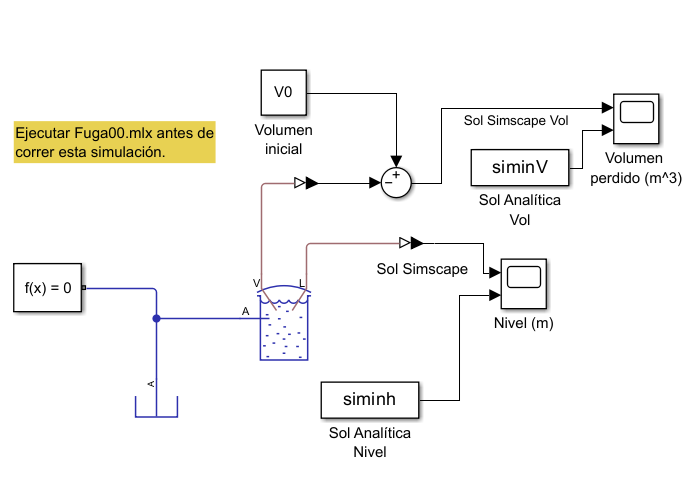

**Figura 4. **Modelo de tanque de descarga en Simscape

Desarrolle una segunda simulación también en Simulink utilizando bloques básicos tales como [Integrator](https://la.mathworks.com/help/simulink/slref/integrator.html), [sqrt](https://la.mathworks.com/help/simulink/slref/sqrt.html) y [gain](https://la.mathworks.com/help/simulink/slref/gain.html). Realice una comparativa con la solucíon analítica obtenida en este *LiveScript*.

## Configuración del tanque con eje axial horizontal

Alternativamente se considera la posibilidad de colocar el tanque con su eje axial de manera horizontal, es decir, "acostado", siempre que se respeten las siguientes características

- La altura del total del contenedor debe seguir siendo igual al tanque parado.

- El volumen total del tanque debe ser igual acostado que parado.

- La toma de salida sigue a nivel del suelo al igual que la versión del tanque parado.

Realice un estudio sobre esta nueva configuración del contendor y conteste las siguientes preguntas.

- ¿Es buena idea esta nueva colocación del contenedor en términos de mejora de la contención de la emergencia del derrame del combustible? 

- ¿Se justifica esta colocación del tanque? 

- Argumente a favor y en contra sobre estas posibles de colocar el contenedor.

## Referencias

### Seguridad Industrial

- Crowl, D. A., y Louvar, J. F. (1990). *Chemical Process Safety: Fundamentals with Applications*. Englewood Cliffs NJ: Prentice Hall.

- Turton, R., Shaeiwitz, J. A., Bhattacharyya, D., y Whiting, W. B. (2018). *Analysis, Synthesis and Design of Chemical Processes* (5.a ed.). Boston MA: Prentice Hall.

### Mecánica de Fluidos e Hidráulica

- Boucher, D. F., y Alves, G. E. (1973). Mecánica de fluidos y de partículas. En R. H. Perry y C. H. Chilton (Eds.), *Biblioteca del Ingeniero Químico* (5.a ed., cap. 5). México, D.F.: McGraw-Hill.

- de Nevers, N. (1991). *Fluid Mechanics for Chemical Engineers* (2.a ed.). Singapore: McGraw-Hill.

- Streeter, V. L., y Wylie, E. B. (1986). *Mecánica de los Fluidos* (8.a ed.). México, D.F.: McGraw-Hill.

### Modelado dinámico y sistemas hidráulicos

- Ogata, K. (2010). *Ingeniería de Control Moderna* (5.a ed.). Madrid: Pearson Eduación.

- Smith, C. A., y Corripio, A. B. (1985). *Control Automático de Procesos Teoría y Práctica*. México, D.F.: Limusa/Grupo Noriega Editores.

### Ecuaciones diferenciales y métodos numéricos

- Vande Wouwer, A., Saucez, P., y Vilas, C. (2014). *Simulation of ODE/PDE Models with MATLAB®, OCTAVE and SCILAB*. Switzerland: Springer.

- Zill, D. G., y Wright, W. S. (2015).* Ecuaciones Diferenciales con problemas de valores en la frontera* (8.a ed.). México, D.F.: Cengage Learning.